clear all;
close all;

tau = 0.05

tau = 0.0500

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


alpha = (s*tau + 1)^2

alpha =
 
  0.0025 s^2 + 0.1 s + 1
 
Continuous-time transfer function.
Model Properties



beta = (0.5*s + 1)^3

beta =
 
  0.125 s^3 + 0.75 s^2 + 1.5 s + 1
 
Continuous-time transfer function.
Model Properties



GHsym = [s^2/alpha, -1/alpha, -1/alpha, 0;
         1/alpha, (alpha - 1/alpha)/s^2, -1/(s^2 * alpha), 1/s^2;
         (1-1/alpha)/beta, -(alpha-1/alpha)/(beta * s^2), 1/(beta*s^2*alpha), -1/(beta*s^2);
         s^2/(beta*alpha), (1-1/alpha)/beta, -1/(beta*alpha), 0]

GHsym =
 
  From input 1 to output...
                s^2
   1:  ----------------------
       0.0025 s^2 + 0.1 s + 1
 
                 1
   2:  ----------------------
       0.0025 s^2 + 0.1 s + 1
 
                              0.0025 s^2 + 0.1 s
   3:  -----------------------------------------------------------------
       0.0003125 s^5 + 0.01438 s^4 + 0.2038 s^3 + 0.9025 s^2 + 1.6 s + 1
 
                                      s^2
   4:  -----------------------------------------------------------------
       0.0003125 s^5 + 0.01438 s^4 + 0.2038 s^3 + 0.9025 s^2 + 1.6 s + 1
 
  From input 2 to output...
                 -1
   1:  ----------------------
       0.0025 s^2 + 0.1 s + 1
 
       6.25e-06 s^4 + 0.0005 s^3 + 0.015 s^2 + 0.2 s
   2:  ---------------------------------------------
                0.0025 s^4 + 0.1 s^3 + s^2
 
                  -6.25e-06 s^4 - 0.0005 s^3 - 0.015 s^2 - 0.2 s
   3:  ---------------------------------------------------------------------
       0.



Gss_q1 = ss(GHsym, 'minimal')

Gss_q1 =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10
   x1       -34.63       -20.7          22      -6.547      0.1158       0.412       4.773      -8.238       1.969       10.13
   x2        7.737      -2.212      -2.058      0.9796    -0.02955     0.01017      0.9466       1.933       1.669       2.252
   x3       -1.452       3.711      -4.877       2.231     -0.5269    -0.04227     -0.8614      0.6478      0.2016       2.335
   x4       0.7539     -0.4602       2.485      -1.579      0.3297     0.01258       0.626      0.4319      0.1058      -1.593
   x5      -0.1019     0.06221     -0.1381     0.09159    -0.02297  -0.0005673     -0.3853     -0.6128     -0.3524     0.01945
   x6     -0.04949     0.03021    -0.06705    -0.02231    -0.09623     0.01471    -0.01844    0.004594    -0.03276    -0.09495
   x7      -0.1413     0.08622     -0.1914    -0.06369      0.1296   -0.005853       1.515   

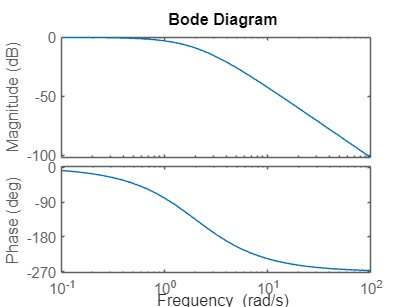


bode(1/beta)

% realised that matlab uses [z; y] when the q1 has asked for [y; z]

% form subsystem from r to e
ny = 2;
nz = 2;
new_order = [ny+1 : ny+nz, 1 : ny];

Gss = ss(Gss_q1.A, Gss_q1.B, Gss_q1.C(new_order, :), Gss_q1.D(new_order, :));


## []


A =  Gss.A;
B = Gss.B;
Bw = Gss.B(:, 1:2);
Bu = Gss.B(:, 3:4);
C = Gss.C(1:2, :);
D = Gss.D;
D_w = Gss.D(1:2, 1:2);
D_u = Gss.D(1:2, 3:4); % goes w then u


n = size(A, 1);
m = size(Bu, 2);

% literally copied exactly from the fucking lecture notes and it doesnt
% work
% UPDATE: IT WORKS

cvx_begin sdp
    variable Y(n,n) symmetric
    variable Z(m,n)
    variable gama

    LMI1 = Y >= 0

 
Constraint accepted
 


    LMI2 = gama <= 0.1

 
Constraint accepted
 


    
    LMI3 = [ (Y*A' + A*Y + Z'*Bu' + Bu*Z),   (Y*C' + Z'*D_u'),          Bw;
            (C*Y + D_u*Z),  -gama*eye(2),      D_w';
            Bw',            D_w,                -gama*eye(2) ] <= 0;
cvx_end

 
Calling SDPT3 4.0: 161 variables, 76 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 76
 dim. of sdp    var  = 24,   num. of sdp  blk  =  2
 dim. of linear var  =  1
 number of nearly dependent constraints = 1
 To remove these constraints, re-run sqlp.m with OPTIONS.rmdepconstr = 1.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.4e+02|3.9e+00|3.0e+04| 4.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.311|0.534|6.5e+02|1.8e+00|2.4e+04|-5.613396e+02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.6

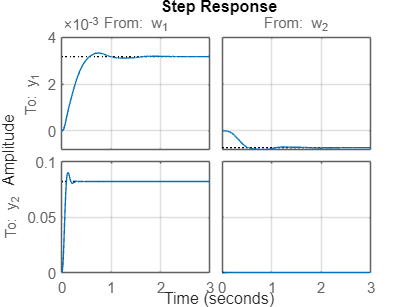

K_g = Z / Y;

A_cl = A + Bu * K_g;
B_cl = Bw;
C_cl = C + D_u * K_g;
D_cl = D_w;

Gcl = ss(A_cl, B_cl, C_cl, D_cl);
% w to y
figure;
Gcl.InputName = {'w_1','w_2'};
Gcl.OutputName = {'y_1','y_2'};
step(Gcl);
grid on;
print(gcf, 'figures/K_g_step.png', '-dpng', '-r300');

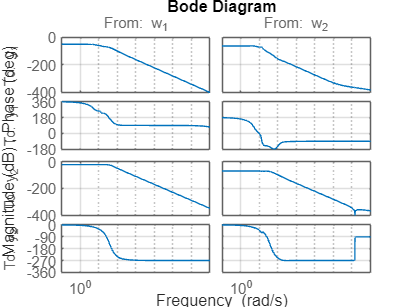

bode(Gcl);
grid on;
print(gcf, 'figures/K_g_bode.png', '-dpng', '-r300');

blk = [1, 0; 1, 0];
[Bounds, mussvInfo] = mussv(Gcl, blk);

Computing bounds... Points completed: 42/42
Computing peak...  Percent completed: 100/100


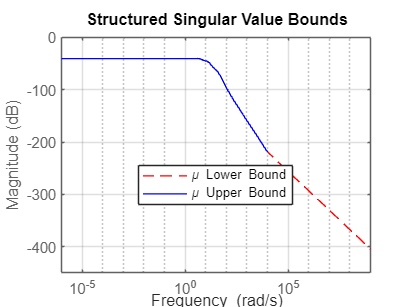

sigmaLower = Bounds(:,1);
sigmaUpper = Bounds(:,2);
figure; 
bodemag(sigmaLower, 'r--', sigmaUpper, 'b-'); 
grid on
legend('\mu Lower Bound','\mu Upper Bound','Location','Best')
title('Structured Singular Value Bounds')
print(gcf, 'figures/structured_singular_values.png', '-dpng', '-r300');

## Passivity LMI

% system definition

tau = 0.05

tau = 0.0500

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


alpha = (s*tau + 1)^2

alpha =
 
  0.0025 s^2 + 0.1 s + 1
 
Continuous-time transfer function.
Model Properties



beta = (1 - 1/alpha)

beta =
 
    0.0025 s^2 + 0.1 s
  ----------------------
  0.0025 s^2 + 0.1 s + 1
 
Continuous-time transfer function.
Model Properties



GHpsym = [1/s, 1/(s*alpha), 1/s, 0;
          1/(s*alpha), 1/s, 0, 1/s;
          beta/(s^2), -beta/(s^2), 1/(s^2), -1/(s^2);
          beta/s, -beta/s, 1/s, -1/s]

GHpsym =
 
  From input 1 to output...
       1
   1:  -
       s
 
                  1
   2:  ------------------------
       0.0025 s^3 + 0.1 s^2 + s
 
           0.0025 s^2 + 0.1 s
   3:  --------------------------
       0.0025 s^4 + 0.1 s^3 + s^2
 
          0.0025 s^2 + 0.1 s
   4:  ------------------------
       0.0025 s^3 + 0.1 s^2 + s
 
  From input 2 to output...
                  1
   1:  ------------------------
       0.0025 s^3 + 0.1 s^2 + s
 
       1
   2:  -
       s
 
          -0.0025 s^2 - 0.1 s
   3:  --------------------------
       0.0025 s^4 + 0.1 s^3 + s^2
 
         -0.0025 s^2 - 0.1 s
   4:  ------------------------
       0.0025 s^3 + 0.1 s^2 + s
 
  From input 3 to output...
       1
   1:  -
       s
 
   2:  0
 
        1
   3:  ---
       s^2
 
       1
   4:  -
       s
 
  From input 4 to output...
   1:  0
 
       1
   2:  -
       s
 
       -1
   3:  ---
       s^2
 
       -1
   4:  --
       s
 
Continuous-time transfer function.
<a href="matla


Gss_q2 = ss(GHpsym, 'minimal')

Gss_q2 =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7
   x1     -0.9832       -25.4     -0.9048      0.3472    -0.06283      0.5933       4.236
   x2       10.85       -36.8     -0.0464     0.09708      0.3928    -0.07737     0.02704
   x3     0.01782      -3.869     -0.1663      0.0406    -0.02086     -0.2268     0.00537
   x4    0.001218     -0.0207  -0.0005376      -30.57       37.88      -3.552    0.009093
   x5    -0.01218      0.2071    0.005377      -2.952      -9.329      0.7826     -0.0252
   x6     -0.1424        2.42     0.06283    -0.02561       1.143     -0.1319     -0.2746
   x7      -1.047       17.79      0.4619     -0.1882      -0.031     -0.2367       -2.02
 
  B = 
              u1         u2         u3         u4
   x1     -2.246     -0.168     0.5359    -0.4231
   x2     -7.722    -0.6887     0.1575    -0.1233
   x3    -0.5259    0.05341     0.1689    -0.1332
   x4    -0.7246      7.773  -0.002691   0.007705
   

ny = 2;
nz = 2;
new_order = [ny+1 : ny+nz, 1 : ny];

Gpss = ss(Gss_q2.A, Gss_q2.B, Gss_q2.C(new_order, :), Gss_q2.D(new_order, :));

% g prefix means its the LMI for the gain

A =  Gpss.A;
B = Gpss.B;
Bw = Gpss.B(:, 1:2);
Bu = Gpss.B(:, 3:4);
Cz = Gpss.C(1:2, :);
D = Gpss.D;
Dzw = Gpss.D(1:2, 1:2);
Dzu = Gpss.D(1:2, 3:4); % goes w then u

% p prefix means its the LMI for passivity
C = Gpss.C

C =     0.1851    0.0773   -1.4027    0.0020   -0.0257    0.0176    0.1114
    0.5134   -0.1008    0.1146    0.0073    0.3809    0.3660    0.5495
    0.3824    0.1410    0.1258    0.0161    0.2198   -1.0863    1.0030
   -0.1311    0.2418    0.0113    0.0087   -0.1611   -1.4522    0.4535


Cy = Gpss.C(3:4, :);
Dyw = Gpss.D(3:4, 1:2);
Dyu = Gpss.D(3:4, 3:4); % goes w then u

## separate LMIs


n = size(A, 1)

n = 7

m = size(Bw, 2)

m = 2


cvx_begin sdp
    variable Y(n,n) symmetric
    variable Z(m,n)
    variable epsilon
    variable gama
    
    %minimise(gama)
    minimise(epsilon) % otherwise makes very high

    LMI1 = Y >= 0

 
Constraint accepted
 


    LMI2 = gama <= 0.1

 
Constraint accepted
 


    
    % gain LMI
    %
    LMI3 = [ (Y*A' + A*Y + Z'*Bu' + Bu*Z),   (Y*Cz' + Z'*Dzu'),          Bw;
            (Cz*Y + Dzu*Z),  -gama*eye(2),      Dzw';
            Bw',            Dzw,                -gama*eye(2) ] <= 0;
    
    LMI4 = epsilon >= 0

 
Constraint accepted
 


    LMI5 = [ Y*A' + A*Y + Bu*Z + Z'*Bu', Bw - Y*Cy' - Z'*Dyu';
             Bw' - Cy*Y-Dyu*Z,   -2*epsilon*eye(2) - (Dyw + Dyw')] <= 0

 
Constraint accepted
 


         
cvx_end

 
Calling SDPT3 4.0: 141 variables, 44 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 44
 dim. of sdp    var  = 27,   num. of sdp  blk  =  3
 dim. of linear var  =  2
 number of nearly dependent constraints = 1
 To remove these constraints, re-run sqlp.m with OPTIONS.rmdepconstr = 1.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+03|1.9e+01|3.6e+04| 8.800000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.431|0.379|1.2e+03|1.2e+01|2.8e+04|-3.011213e-01 -4.526649e+01| 0:0:00| chol  1  1 
 2|0.9


K_p = Z / Y;

Gpcl_w_to_y = ss(A + Bu * K_p, Bw, Cy + Dyu * K_p, Dyw);
assert(isPassive(Gpcl_w_to_y))

% w to e
A_pcl = A + Bu * K_p;
B_pcl = Bw;
C_pcl = Cz + Dzu * K_p;
D_pcl = Dzw;

Gpcl = ss(A_pcl, B_pcl, C_pcl, D_pcl);

Gpcl.InputName = {'w_1','w_2'};
Gpcl.OutputName = {'e_1','e_2'};

isPassive(Gpcl)

ans = logical
   0


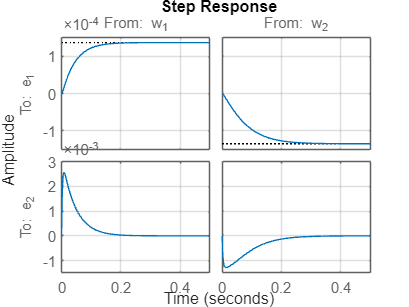


step(Gpcl)
grid on;
print(gcf, 'figures/K_p_step.png', '-dpng', '-r300');

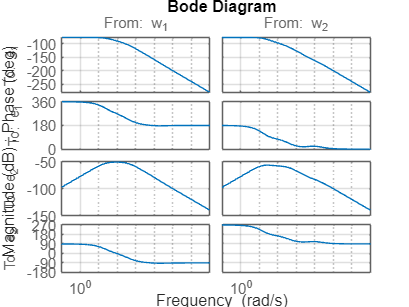

bode(Gpcl)
grid on;
print(gcf, 'figures/K_p_bode.png', '-dpng', '-r300')


%passiveplot(Gpcl)
%nyquist(Gpcl)


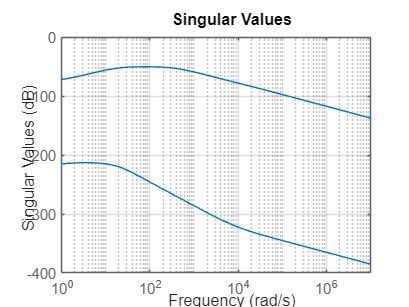

sigma(Gpcl)
grid on;
print(gcf, 'figures/K_p_sigma.png', '-dpng', '-r300')